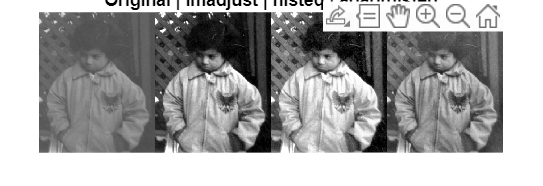

I1 = imread('pout.tif');
I2 = imread('tire.tif');

A1 = imadjust(I1);
H1 = histeq(I1);
C1 = adapthisteq(I1);

A2 = imadjust(I2);
H2 = histeq(I2);
C2 = adapthisteq(I2);

figure('Name','pout.tif enhancement');
montage({I1,A1,H1,C1},'Size',[1 4]);
title('Original | imadjust | histeq | adapthisteq');

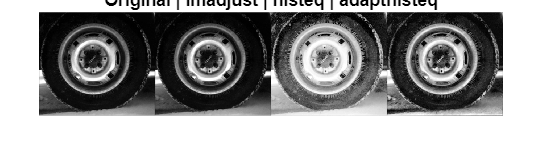


figure('Name','tire.tif enhancement');
montage({I2,A2,H2,C2},'Size',[1 4]);
title('Original | imadjust | histeq | adapthisteq');

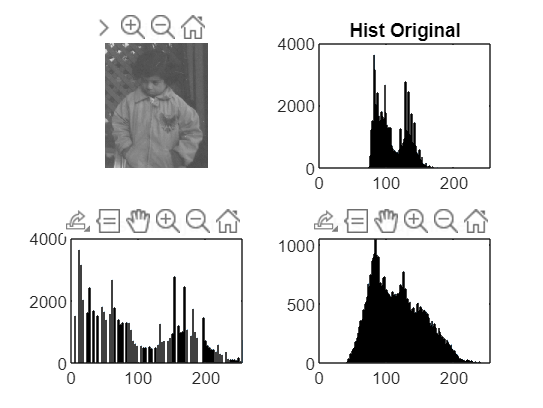


figure('Name','pout.tif histograms');
tiledlayout(2,2);
nexttile; imshow(I1); title('Original'); 
nexttile; histogram(I1(:),0:255); xlim([0 255]); title('Hist Original');
nexttile; histogram(A1(:),0:255); xlim([0 255]); title('Hist imadjust');
nexttile; histogram(C1(:),0:255); xlim([0 255]); title('Hist adapthisteq');

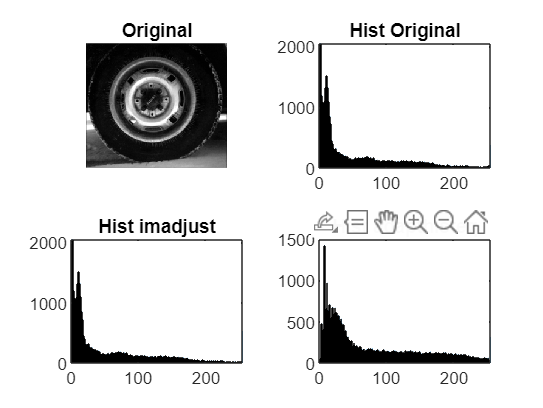


figure('Name','tire.tif histograms');
tiledlayout(2,2);
nexttile; imshow(I2); title('Original');
nexttile; histogram(I2(:),0:255); xlim([0 255]); title('Hist Original');
nexttile; histogram(A2(:),0:255); xlim([0 255]); title('Hist imadjust');
nexttile; histogram(C2(:),0:255); xlim([0 255]); title('Hist adapthisteq');

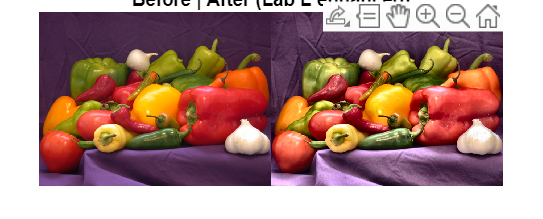


I = imread('peppers.png');
lab = rgb2lab(I);
L = lab(:,:,1)/100;
L2 = adapthisteq(L);
lab2 = lab;
lab2(:,:,1) = L2*100;
I_enh = lab2rgb(lab2,'OutputType','uint8');

figure('Name','Lab luminance enhancement');
montage({I,I_enh},'Size',[1 2]);
title('Before | After (Lab L enhanced)');

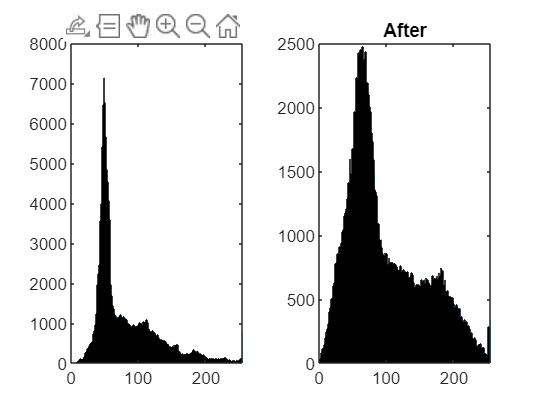


G_before = rgb2gray(I);
G_after  = rgb2gray(I_enh);

figure('Name','Luminosity histograms (grayscale view)');
tiledlayout(1,2);
nexttile; histogram(G_before(:),0:255); xlim([0 255]); title('Before');
nexttile; histogram(G_after(:),0:255);  xlim([0 255]); title('After');